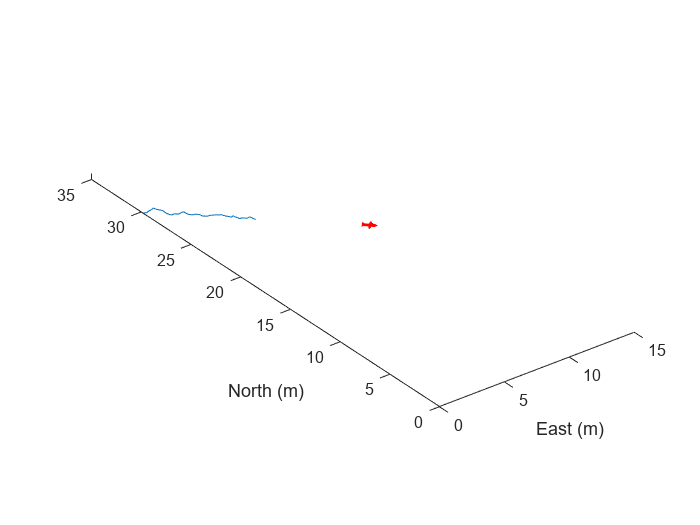

% Use fixed random seed for simulation repeatablity.
rng(0)

% Create a scenario that runs for 10 seconds.
s = uavScenario("StopTime",10,"HistoryBufferSize",200);

% Create a fixed-wing target that moves from [30 0 0] to [20 10 0].
target = uavPlatform("Target",s,"Trajectory",waypointTrajectory([30 0 0; 20 10 0],"TimeOfArrival",[0 10])); 
updateMesh(target,"fixedwing", {1}, [1 0 0], eul2tform([0 0 pi]));

% Create a quadrotor that moves from [0 0 0] to [10 10 0].
egoMultirotor = uavPlatform("EgoVehicle",s,"Trajectory",waypointTrajectory([0 0 0; 0 0 0],"TimeOfArrival",[0 5]));
updateMesh(egoMultirotor,"quadrotor",{1},[0 1 0],eul2tform([0 0 pi]));

% Mount a radar on the quadrotor.
radarSensor = radarDataGenerator("no scanning","SensorIndex",1,"UpdateRate",10,...
    "FieldOfView",[120 80],...
    "HasElevation", true,...
    "ElevationResolution", 3,...
    "AzimuthResolution", 1, ...
    "RangeResolution", 10, ... meters
    "RangeRateResolution",3,...
    "RangeLimits", [0 750],...
    "TargetReportFormat","Tracks",...
    "TrackCoordinates",'Scenario',...
    "HasINS", true,...
    "HasFalseAlarms",true,...
    "FalseAlarmRate",1e-5,...
    "HasRangeRate",true,...
    "FalseAlarmRate", 1e-7);

% Create the sensor. ExampleHelperUAVRadar inherits from the uav.SensorAdaptor class.
radar = uavSensor("Radar",egoMultirotor,ExampleHelperUAVRadar(radarSensor),"MountingAngles", [0 0 0]);
[ax,plotFrames] = show3D(s);
xlim([-0,15]);
ylim([-0,35]);
hold on
% Add detection and sensor field of view to the plot.
trackSquare = plot3(plotFrames.NED,nan,nan,nan,"-");
radarDirection = hgtransform("Parent",plotFrames.EgoVehicle.Radar,"Matrix",eye(4));
coverageAngles = linspace(-radarSensor.FieldOfView(1)/360*pi, radarSensor.FieldOfView(1)/360*pi,128);
coveragePatch = patch([0 radarSensor.RangeLimits(2)*cos(coverageAngles) 0], ...
    [0 radarSensor.RangeLimits(2)*sin(coverageAngles) 0],...
    "blue","FaceAlpha",0.3,...
    "Parent",radarDirection);
hold(ax,"off");

% Start simulation.
setup(s);
while advance(s)
    % Update sensor readings and read data.
    updateSensors(s);
    
    % Plot updated radar FOV.
    egoPose = read(egoMultirotor);
    radarFOV = coverageConfig(radarSensor, egoPose(1:3),quaternion(egoPose(10:13)));
    radarDirection.Matrix = eul2tform([radarFOV.LookAngle(1)/180*pi 0 0]);
    
    % Obtain detections from the radar and visualize them.
    [isUpdated,time,confTracks,numTracks,config] = read(radar);
    if numTracks > 0
        trackSquare.XData = [trackSquare.XData,confTracks(1).State(1)];
        trackSquare.YData = [trackSquare.YData,confTracks(1).State(3)];
        trackSquare.ZData = [trackSquare.ZData,confTracks(1).State(5)];
        drawnow limitrate
    end
    
    show3D(s,"FastUpdate", true,"Parent",ax);
    pause(0.1);
end


% Display the radar outputs in degrees and meters
fprintf('Azimuth: %.2f degrees\n', azimuth_degrees);

Azimuth: 85.94 degrees


fprintf('Elevation: %.2f degrees\n', elevation_degrees);

Elevation: 28.65 degrees


fprintf('Range: %.2f meters\n', range_meters);

Range: 100.00 meters
